Length = input("Comprimento da parte do carro que passará no laser:");
Track = input("Comprimento da pista:");
N = input("Quantas voltas serão dadas:");

avgs = [];
insts = [];

for i = 1:N
    avgtime = input(['Tempo até completar a ' num2str(i) 'º volta:']);
    avgs = [avgs, Track/avgtime];
    insttime = input("Intervalo de tempo que o carro ficou no photogate:");
    insts = [insts, Length/insttime];
end

a = 1;
for i = avgs
    disp(['A velocidade média da ' num2str(a) 'º volta foi de ' num2str(i*3.6) ' km/h']);
    a = a + 1;
end

A velocidade média da 1º volta foi de 40.9091 km/h
A velocidade média da 2º volta foi de 42.73 km/h
A velocidade média da 3º volta foi de 41.2607 km/h
A velocidade média da 4º volta foi de 40.5634 km/h
A velocidade média da 5º volta foi de 42.6036 km/h
A velocidade média da 6º volta foi de 41.0256 km/h
A velocidade média da 7º volta foi de 41.7391 km/h
A velocidade média da 8º volta foi de 41.2607 km/h
A velocidade média da 9º volta foi de 40.7932 km/h
A velocidade média da 10º volta foi de 41.6185 km/h



b = 1;
for i = insts
    disp(['A velocidade instantânea da ' num2str(b) 'º volta foi de ' num2str(i*3.6) ' km/h']);
    b = b + 1;
end

A velocidade instantânea da 1º volta foi de 2 km/h
A velocidade instantânea da 2º volta foi de 2.1429 km/h
A velocidade instantânea da 3º volta foi de 2.1951 km/h
A velocidade instantânea da 4º volta foi de 2.093 km/h
A velocidade instantânea da 5º volta foi de 2.0455 km/h
A velocidade instantânea da 6º volta foi de 2.1429 km/h
A velocidade instantânea da 7º volta foi de 2.1951 km/h
A velocidade instantânea da 8º volta foi de 2.093 km/h
A velocidade instantânea da 9º volta foi de 2.1429 km/h
A velocidade instantânea da 10º volta foi de 2.1951 km/h


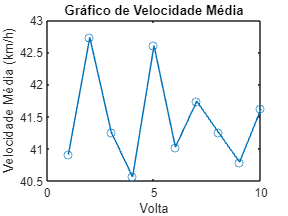


% Gráfico de Velocidade Média
figure;
volta = 1:N;
velocidadeMedia = avgs*3.6;
plot(volta, velocidadeMedia, 'o-');
xlabel('Volta');
ylabel('Velocidade Média (km/h)');
title('Gráfico de Velocidade Média');

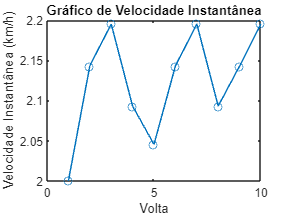


% Gráfico de Velocidade Instantânea
figure;
volta = 1:N;
velocidadeInstantanea = insts*3.6;
plot(volta, velocidadeInstantanea, 'o-');
xlabel('Volta');
ylabel('Velocidade Instantânea (km/h)');
title('Gráfico de Velocidade Instantânea');


avgs = sort(avgs);
insts = sort(insts);
disp(['A maior velocidade média foi: ' num2str(avgs(end)*3.6) ' km/h']);

A maior velocidade média foi: 42.73 km/h


disp(['A maior velocidade instantânea foi: ' num2str(insts(end)*3.6) ' km/h']);

A maior velocidade instantânea foi: 2.1951 km/h
